# 主计算程序

clear;

## 常量参数

global g nu a b Re1 Re2 Re3;
%单位转换关系
cmTom=0.01;
cmTomm=10;
mmTom=0.001;
inchtocm=2.54;
FrTomm=1/3;
Ltom3=0.001;
mintos=60;
mmHgtoPa=133.322;
PatommHg=1/133.322;
%长度,unit=cm
L0=15;
a1=15;
a2=10;
a3=2;
Ha=50;
v1=15;
v3=2;
%直径,unit=mm
Phi0=0.375*inchtocm*cmTomm;
%角度
theta1=90;%单位为度
theta2=135;%单位为度
%流体参数
rho=1065;%单位kg/m^3;
mu=0.004;%单位kg/(m*s);
g=9.8;%单位m/s^2;
nu=mu/rho;
%边界条件
POUT_a=0;%单位Pa
POUT_v=0;%单位pa



Re1=2040;
Re2=3080;
[a,b]=TurnAround(Re1,Re2);

## 统一单位

L0=L0*cmTom

L0 = 0.1500

a1=a1*cmTom

a1 = 0.1500

a2=a2*cmTom;
a3=a3*cmTom;
Ha=Ha*cmTom;
v1=v1*cmTom;
v3=v3*cmTom;
Phi0=Phi0*mmTom;



## 初始条件


Q0_gather=[2.06 	3.05 	4.05 	5.04 	6.04 	7.06 ];
% for i=1:7
%     Da_gather(7*i-6:7*i)=11+2*i;
%     Dv_gather(7*i-6:7*i)=13:2:25;
% end


 %Da_gather(:)=13:0.2:23;
Da_gather=[19,19,19,17,17,17];
Dv_gather=[17,19,21,17,19,21];
La_gather=[18,18,18,18,18,18];
Lv_gather=[50,50,50,50,50,50];
% Lv_gather=30:1:70;
 num_case=length(Lv_gather);
% Da_gather=19*ones(num_case,1);
% Dv_gather=19*ones(num_case,1);
% La_gather=18*ones(num_case,1);
% Lv_gather=50*ones(num_case,1);
for j=1:num_case

    v2=70;
    
    Da=(Da_gather(j)-2)*FrTomm*mmTom;
    Dv=(Dv_gather(j)-2)*FrTomm*mmTom;
    La=La_gather(j)*cmTom;
    v2=v2*cmTom;%可更改
    Lv=Lv_gather(j)*cmTom;
    
    theta3=rad2deg(atan((Phi0-Dv)/(2*v3)));%单位为度
    theta4=rad2deg(atan((Phi0-Da)/(2*a3)));
    
    A0=Phi0^2*pi/4;
    Av=Dv^2*pi/4;
    Aa=Da^2*pi/4;

    HYa=L0+a1*sin(pi/4);
    HYv=L0+v1*sin(pi/4);
 

for i=1:1:length(Q0_gather)
    beita0=0;
    beita=0.5;
    beita1=1;
    residual=1;
    QIN=Q0_gather(i);%单位L/min
    QIN=QIN*Ltom3/mintos;%单位m^3/s
    UIN=QIN/A0;%入口速度m/s 等价于入口流量2L/min 可更改
%速度
while (abs(residual)>0.01)
U1v=beita*UIN;


## 连续方程

U1a=UIN-U1v;
U2v=U1v*A0/Av;
U2a=(UIN-U1v)*A0/Aa;


## 动量方程

%弯头损失的计算
H12v=ElbowLoss(theta2,U1v);
H12a=ElbowLoss(theta2,U1a);
H34a=ElbowLoss(theta1,U1a);

%渐缩管道的损失计算
H34v=TaperLoss(theta3,Phi0,Dv,U2v);
H56a=TaperLoss(theta4,Phi0,Da,U2a);

%沿程损失计算

H23v=FlowLoss(v2,Phi0,U1v);
H4out=FlowLoss(Lv,Dv,U2v);

H23a=FlowLoss(Ha,Phi0,U1a);
H45a=FlowLoss(a2,Phi0,U1a);
H6out=FlowLoss(La,Da,U2a);

%Y形分叉
[~,K]=JunctionLossCoefficient_10([UIN,-U1v,-U1a],[A0,A0,A0],[-pi/2,3*pi/4,pi/4]);

%动量方程
K1v=K(1);
K1a=K(2);
H01v=0.5*K1v*UIN^2/g;
H01a=0.5*K1a*UIN^2/g;
P1v=POUT_v+0.5*rho*(U2v^2-U1v^2)+rho*g*(H12v+H23v+H34v+H4out)+rho*g*HYv;
P1a=POUT_a+0.5*rho*(U2a^2-U1a^2)+rho*g*(H12a+H23a+Ha+H45a+H56a+H6out)+rho*g*HYa;%可能不需要加入

Pin=P1v+0.5*rho*(U1v^2-UIN^2)+rho*g*H01v;
Pin2=P1a+0.5*rho*(U1a^2-UIN^2)+rho*g*H01a;

residual=Pin-Pin2;

if residual>0
    jie=beita;
    beita=(beita0+beita)/2;
    beita1=jie;
else
    jie=beita;
    beita=(beita+beita1)/2;
    beita0=jie;
end
end    

## 由速度计算其他参量

U1v=beita*UIN;
U1a=UIN-U1v;
U2v=U1v*A0/Av;
U2a=(UIN-U1v)*A0/Aa;

sPin=Pin-0.5*rho*UIN^2;
dPa=POUT_a+0.5*rho*U2a^2;
dPv=POUT_v+0.5*rho*U2v^2;
deltasP=(sPin-POUT_a)*PatommHg;
deltadP=(Pin-dPa)*PatommHg;

Qv=U2v*Av;
Qa=U2a*Aa;
vbili(j,i)=Qv/QIN;
abili(j,i)=Qa/QIN;
H(i+(j-1)*length(Q0_gather),:)=[H01a H12a H23a H34a H45a H56a H6out H01v H12v H23v H34v H4out];
Hp(i+(j-1)*length(Q0_gather),:)=[deltasP,deltadP];
end
end

## 导入实验数据

### 随流量变化

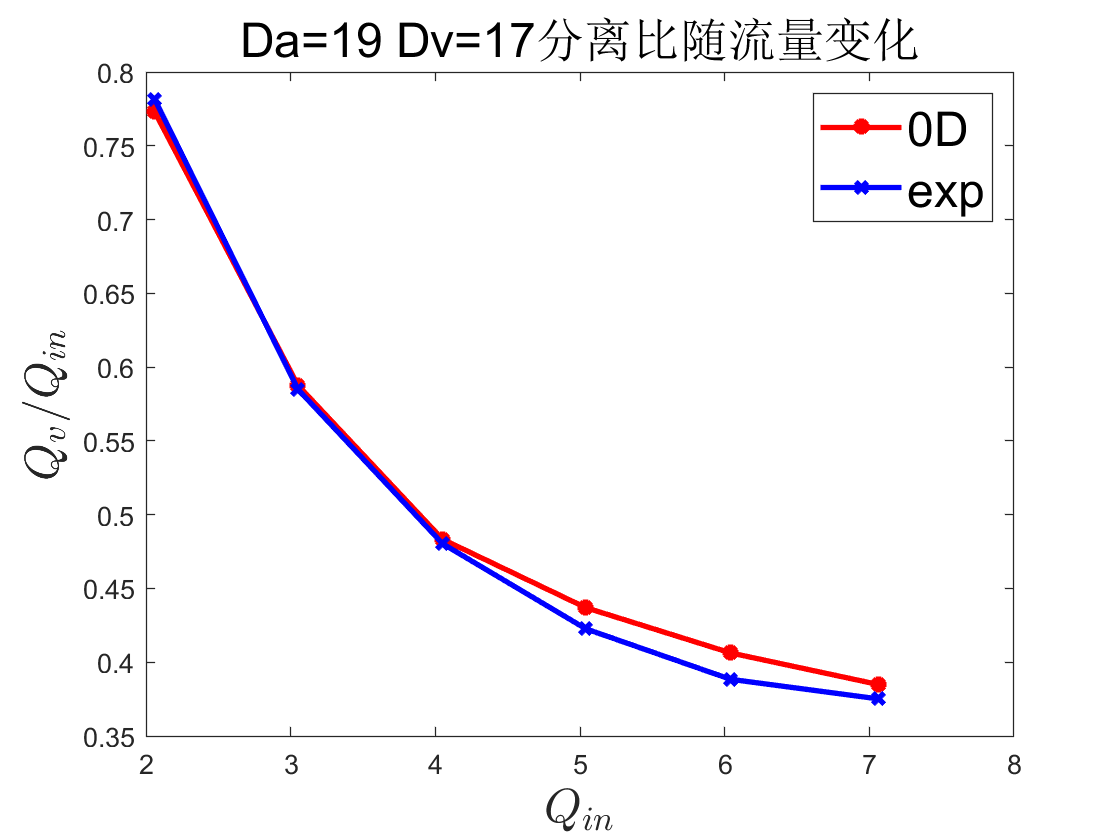

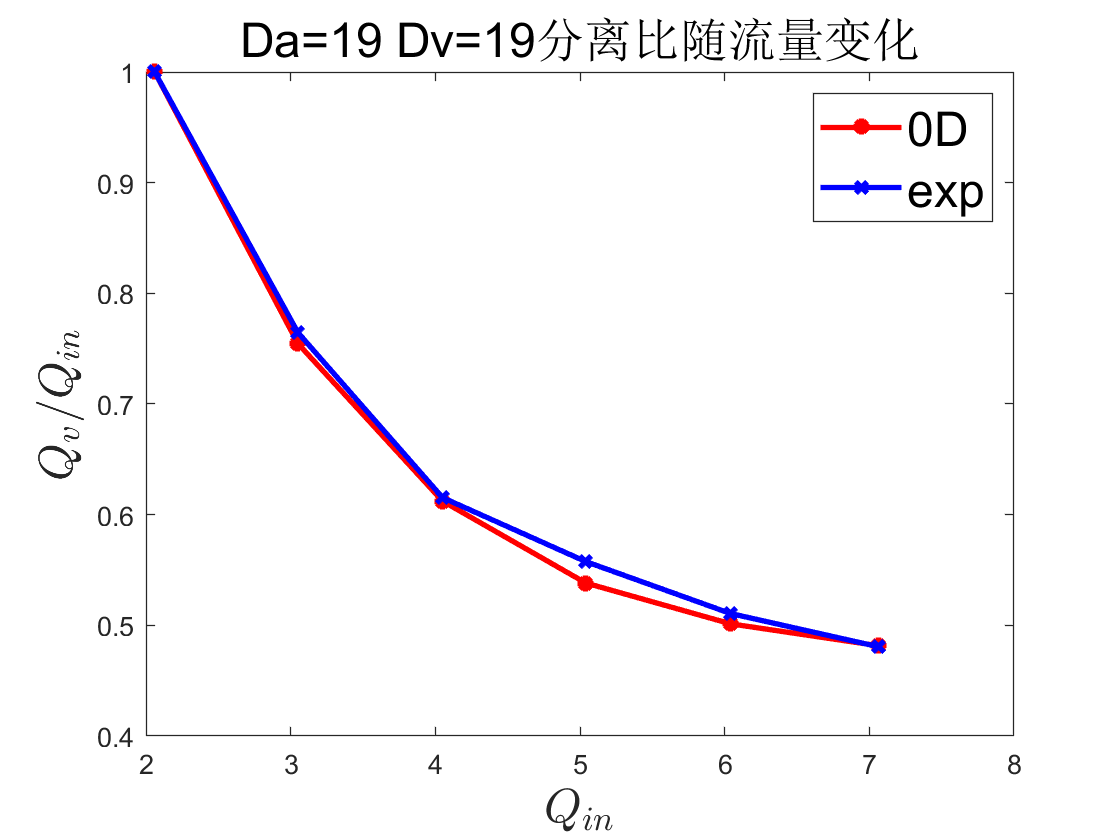

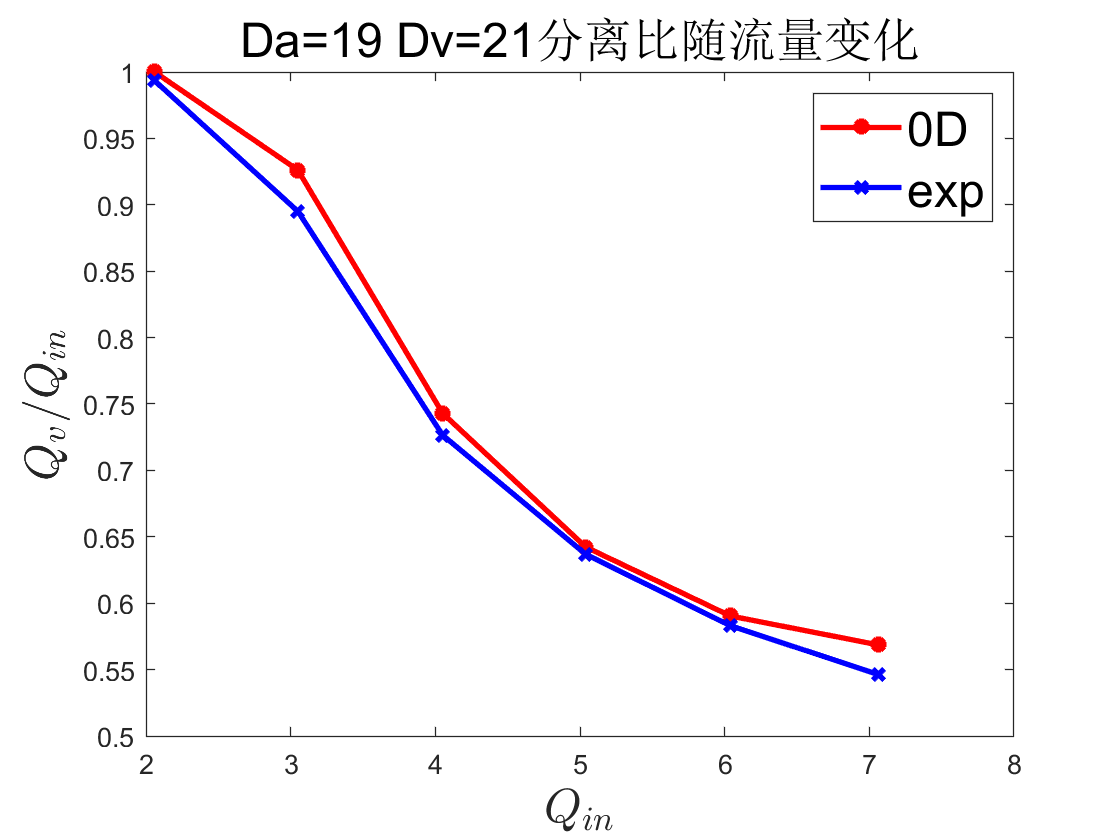

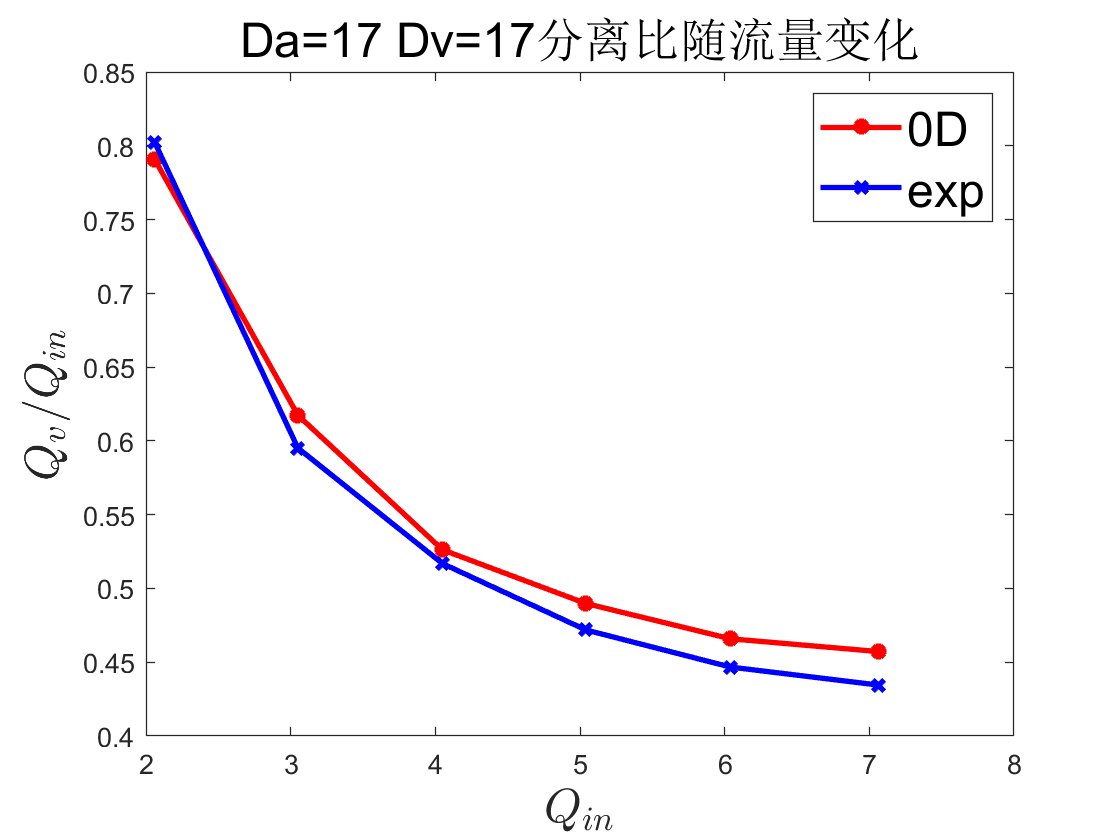

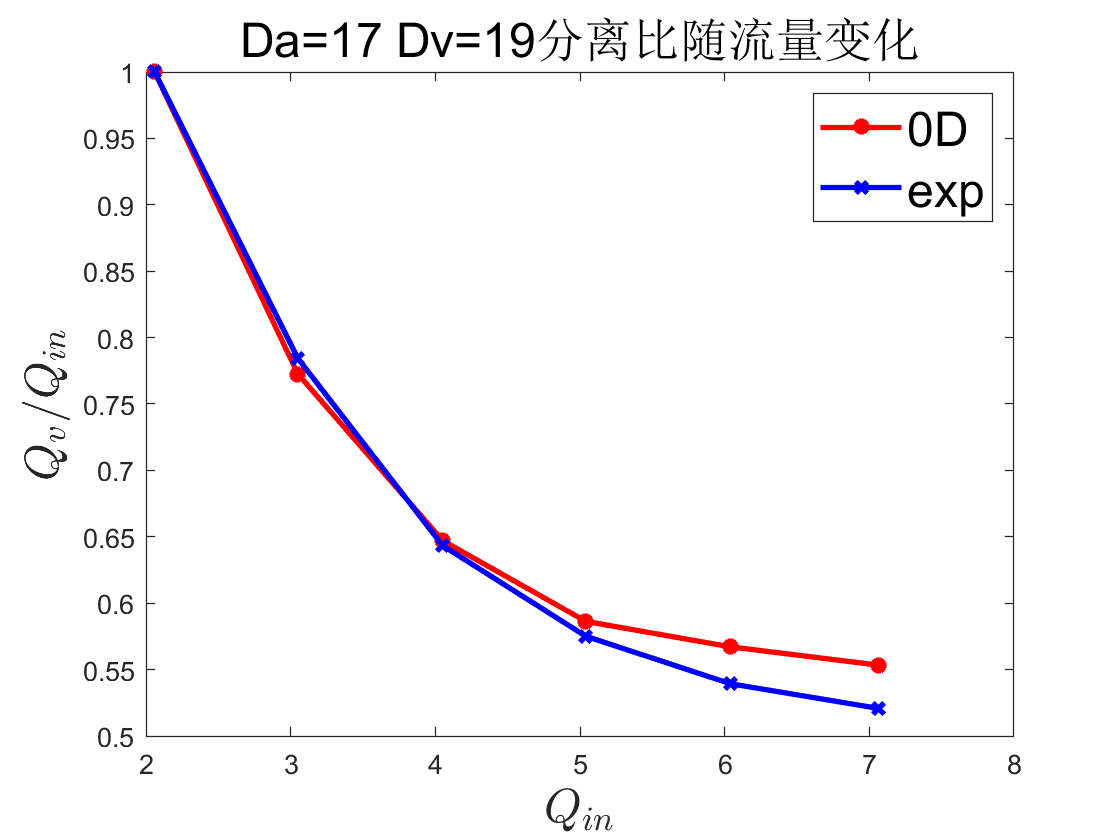

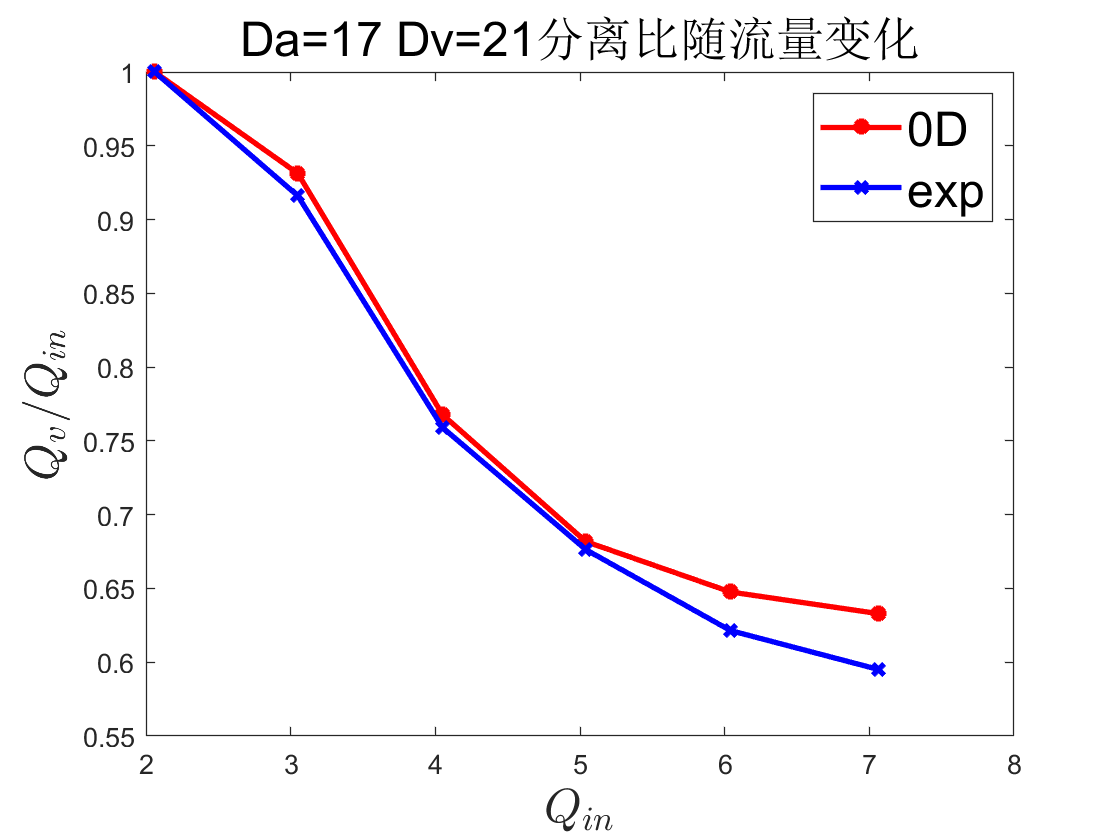


exp=xlsread('exp');
for j=1:num_case
h=figure(j);
plot(Q0_gather,vbili(j,:),'-r*','LineWidth',2);
hold on;
plot(Q0_gather,exp(j,:),'-bx','LineWidth',2);
ti=title(['Da=',num2str(Da_gather(j)),' Dv=',num2str(Dv_gather(j)),'分离比随流量变化']);
ti.FontSize=18;
lg=legend("0D","exp");
lg.FontSize=18;
xlabel('$Q_{in}$','interpreter','latex', 'FontSize', 18);
ylabel('$Q_{v}/Q_{in}$','interpreter','latex', 'FontSize', 18);
% set(gca,'FontSize',18);
% set(h,'PaperPositionMode','manual');
% set(h,'PaperUnits','points');
% set(h,'PaperPosition',[0,0,600,450]);
% string1=['Q-zuhe',num2str(j),'.jpg'];
% print(h,string1,'-r600','-djpeg');
end

### 随案例变化

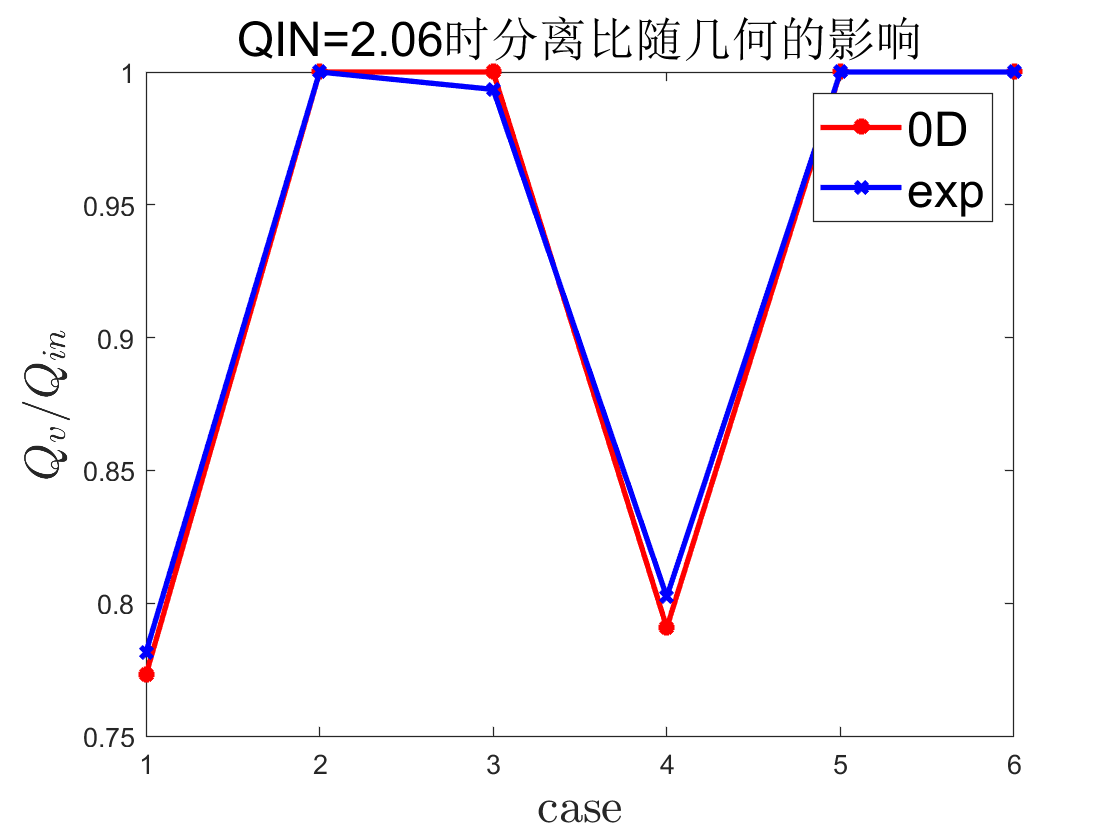

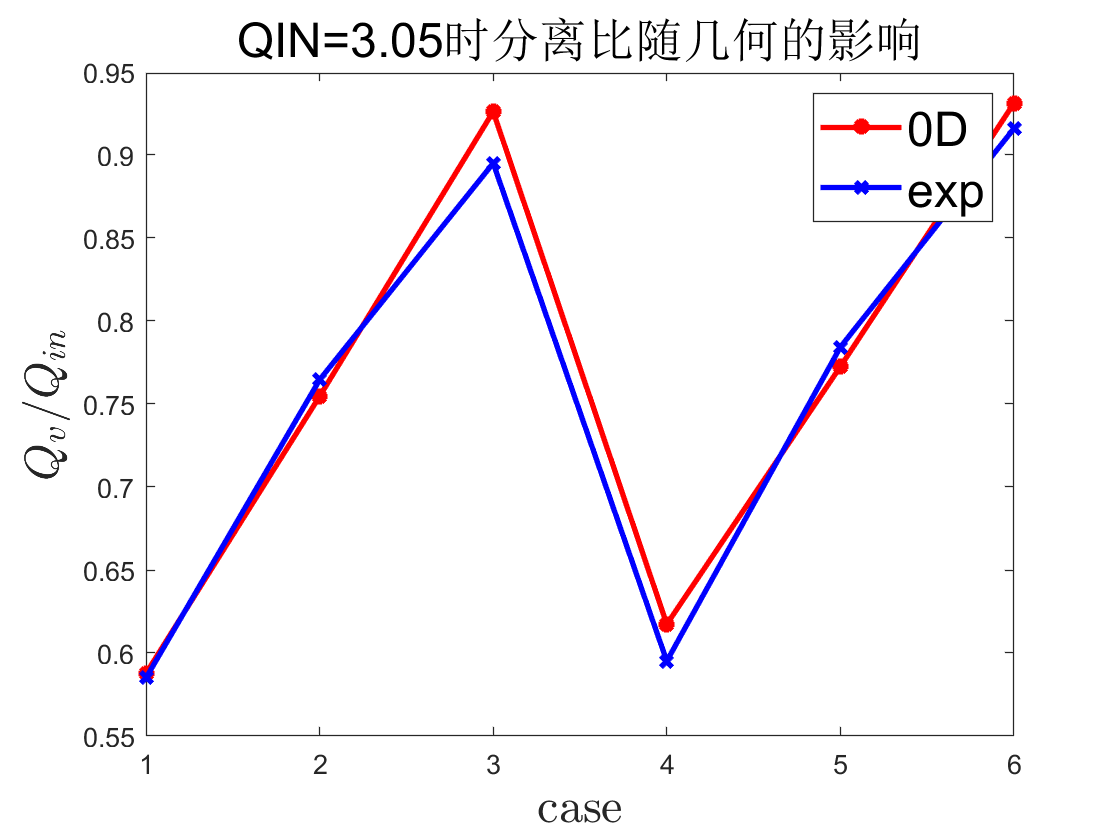

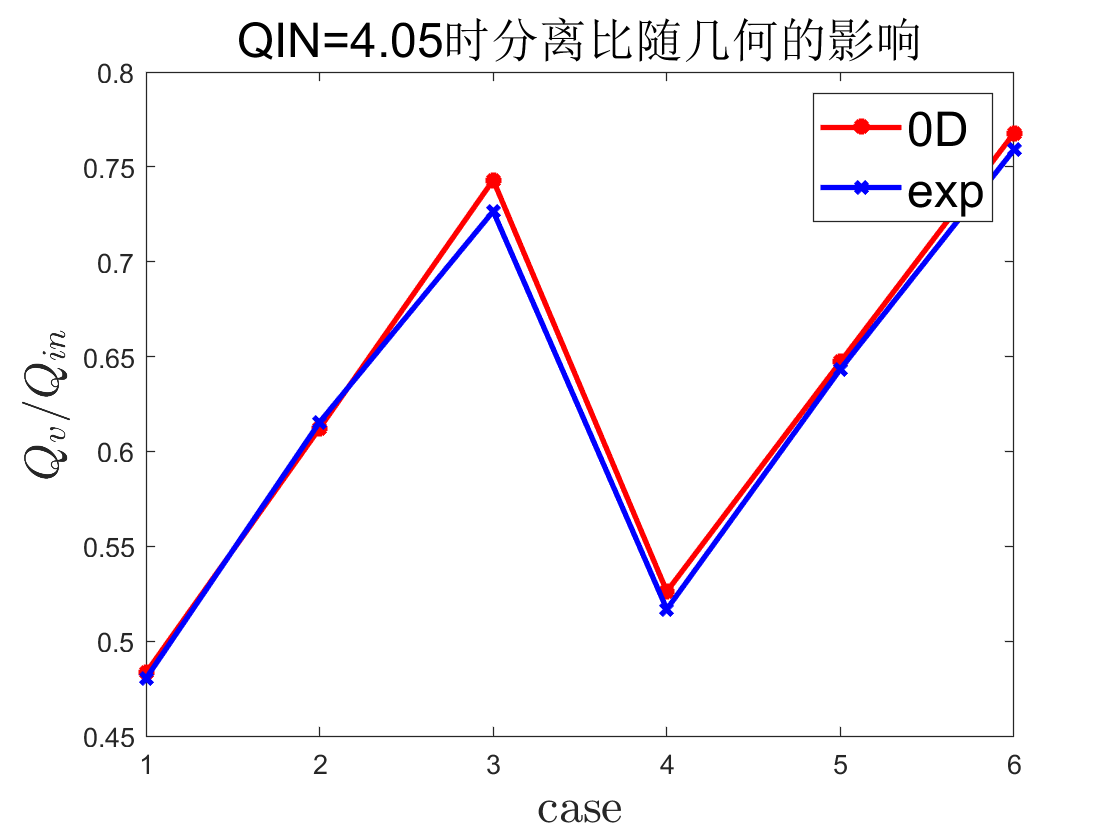

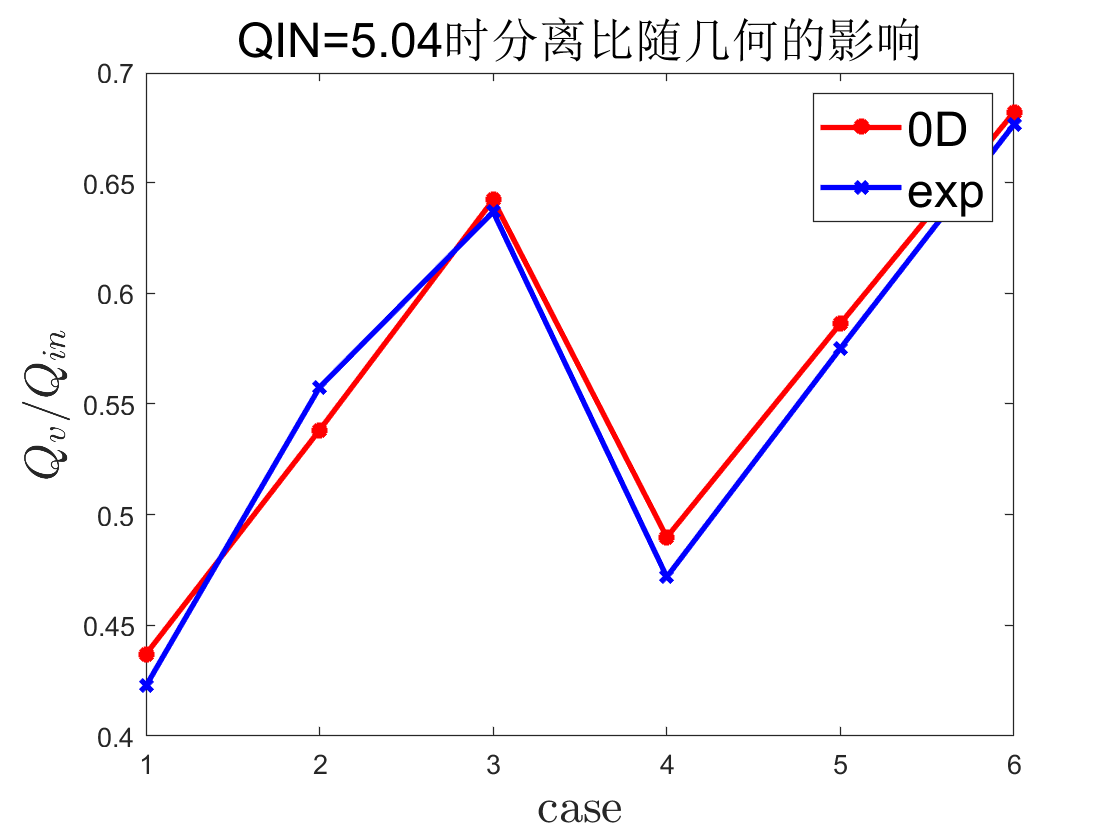

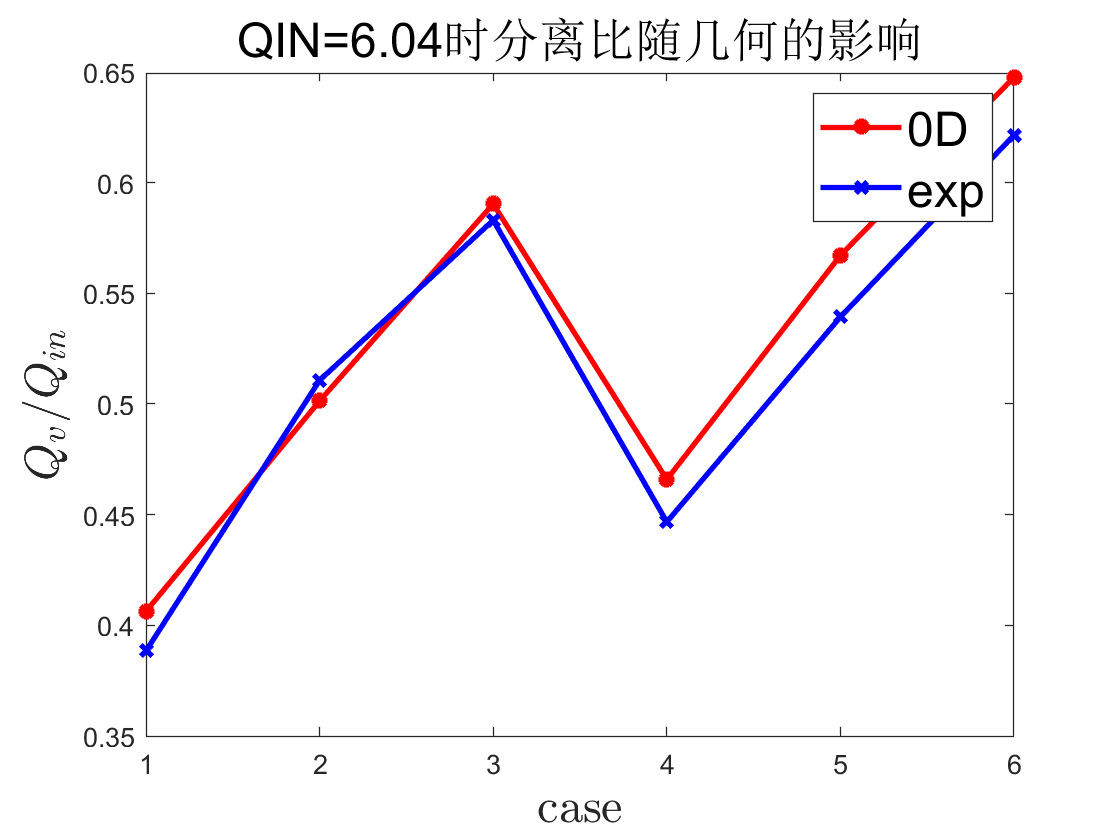

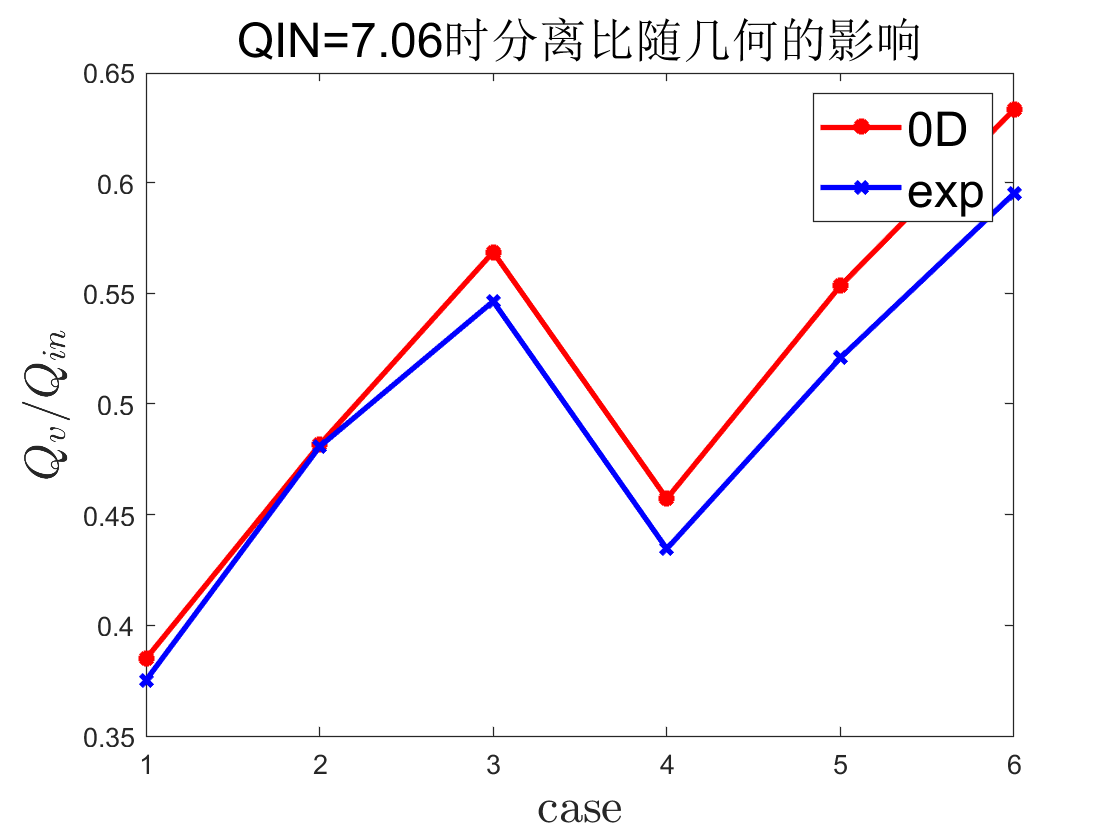

for j=1:num_case
h=figure(j+num_case);
plot(1:num_case,vbili(:,j),'-r*','LineWidth',2);
hold on;
plot(1:num_case,exp(:,j),'-bx','LineWidth',2);
ti=title(['QIN=',num2str(Q0_gather(j)),'时分离比随几何的影响']);
ti.FontSize=18;
lg=legend("0D","exp");
lg.FontSize=18;
xlabel('case','interpreter','latex', 'FontSize', 18);
ylabel('$Q_{v}/Q_{in}$','interpreter','latex', 'FontSize', 18);
% set(gca,'FontSize',18);
% set(h,'PaperPositionMode','manual');
% set(h,'PaperUnits','points');
% set(h,'PaperPosition',[0,0,600,450]);
% string1=['case-zuhe',num2str(j),'.jpg'];
% print(h,string1,'-r600','-djpeg');
end


H=[H*rho*g*PatommHg,Hp]

H =     0.5710    0.0087    0.5786    0.0470    0.1157    0.1510    1.6627    0.2353    0.1010    2.7592    6.2616   25.9558   60.8024   61.3484
    0.8208    0.0630    1.5562    0.3401    0.3112    1.0925    4.4721    0.5844    0.1280    3.1059    7.9338   29.2168   66.1964   65.4711
    1.1638    0.1744    2.5897    0.9417    0.5179    3.0256    7.7381    1.2430    0.1526    3.3916    9.4607   36.7146   74.8669   70.8133
    1.6590    0.3207    3.5118    1.7318    0.7024    5.5640   17.8023    2.1229    0.1932    3.8159   11.9757   50.6822   91.6928   83.1977
    2.2718    0.5122    4.7712    2.7653    0.9542    8.8844   29.1503    3.2618    0.2399    4.2523   14.8717   68.1546  112.2165   97.7604
    3.0142    0.7511    8.0545    4.0553    1.6109   13.0291   40.7514    4.6757    0.2942    4.7087   18.2355   90.0755  137.5070  115.5078
   -0.6147         0       NaN         0       NaN         0       NaN    0.3125    0.1690    3.5692    2.9323   20.5933   53.1699   54.0972
    1.200

Head=["H01a","H12a"," H23a","H34a"," H45a","H56a", "H6out","H01v"," H12v"," H23v"," H34v"," H4out","deltasP","deltadP","vbili"];
xlswrite("exp.xlsx",Head,10,"B1");

错误使用 xlswrite (第 224 行)
文件 F:\Programm\MATLAB\ECMO管道流动\exp.xlsx 不可写。它可能被其他进程锁定。

xlswrite("exp.xlsx",H,10,"B2");